# M E 325 Supplemental Homework 1

### Group 6

#### Parker Wilson, Preston Witte, Mike Lawlor, Justin Merkel

## Determine

- The **fatigue strength**, $S_f$, of a material, at a specified number of stress cycles, $N$, using correction factors for sizing, temperature, loading, reliability, surface treatment, and miscellaneous effects

- The **fatigue stress concentration factors**, $K_f$, that should be applied to cyclical stresses

- **Mean and alternating von Mises stresses**, $\sigma_m^{\prime }$, $\sigma_a^{\prime }$

- **Factors of safety**, $N$, against fatigue and yielding

#### Specimen Loading and relevant data:

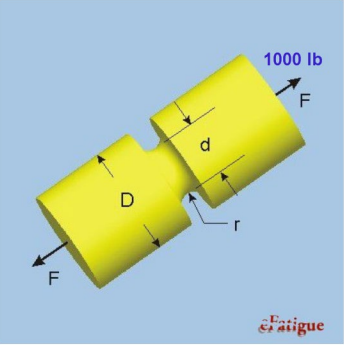    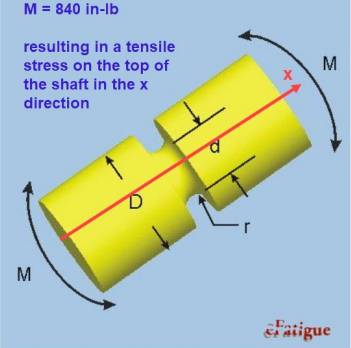    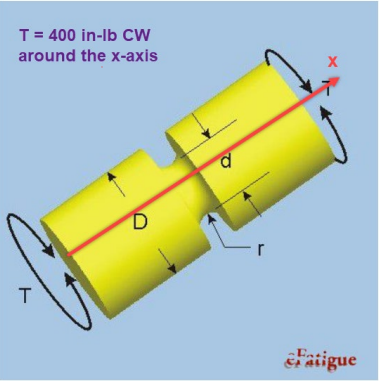    

Fx1 = 1000

Fx1 = 1000

Mx1 = 840

Mx1 = 840

Tx1 = 400

Tx1 = 400

The specimen pictured is a cylinder, with a U-shaped groove and the following dimensions:

The major diameter, $D$, of the shaft is 2.0 inches and the minor diameter, $d$, is 1.75 inches. The radius of the groove, $r$, is 0.25 inches.

D = 2

D = 2

d = 1.75

d = 1.7500

r = 0.25

r = 0.2500

#### Material Properties:

The material from which the shaft is fabricated has an ultimate tensile strength, $S_{\textrm{ut}}$, of 90 kpsi and the yield strength, $S_y$, of the material is 75 kpsi.

S_ultimate = 90

S_ultimate = 90

S_yield = 75

S_yield = 75

#### Relevant information for Marin endurance strength adjustment factors:

The **surface** of the shaft is machined (Table 6.2), and the shaft is rotating (**if the shaft is not rotating an equivalent diameter replaces the diameter used in the sizing adjustment factor**: $d_e =\ldotp 370d$)

d_e = 0.370 * d

d_e = 0.6475

The **operating temperature** of the shaft is $600\;\degree F$ and **room temperature** is $72\;\degree F$.

T_op = 600

T_op = 600

T_room = 72

T_room = 72

The **material reliability** is 99% (Table 6.4) 

There is no impact on the fatigue life of the shaft based on **miscellaneous effects**.

#### 2nd Half of loading cycle

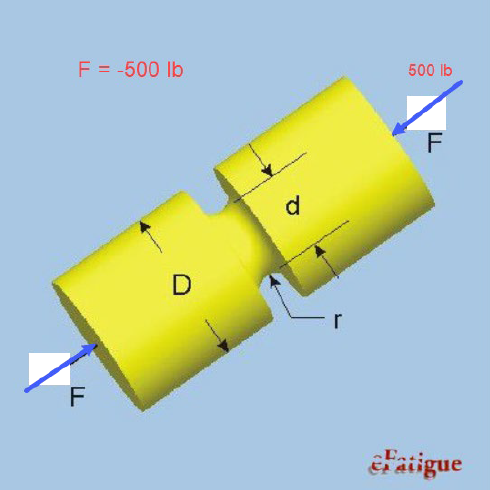    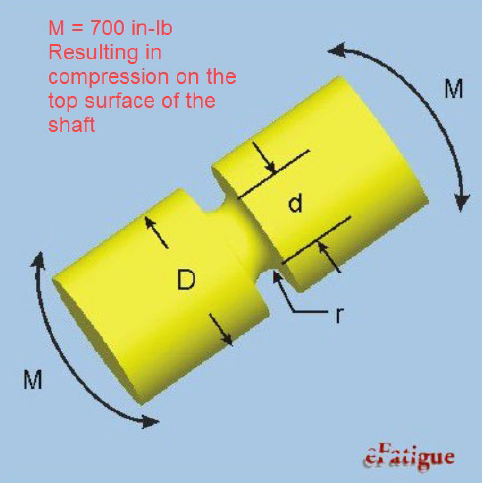    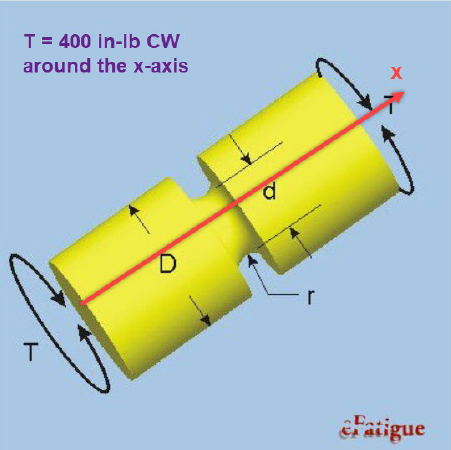

Fx2 = -500

Fx2 = -500

Mx2 = -700

Mx2 = -700

Tx2 = 400

Tx2 = 400

#### Submit:

- Calculations detailing determination of all parameters.

- Determine the factor of safety against yielding and fatigue for the loadings and conditions given at **50,000 stress cycles**.

- Create Goodman and Langer failure envelopes and add the coordinates for $\sigma_a^{\prime }$ and $\sigma_m^{\prime }$. Submit a printout of the failure envelopes and include the load line.

The types of loading experienced by the specimen are axial, bending, and torsion.

Determine stress concentration factors for each type of loading from eFatigue website.

Axial:

K_t_axial = 1.94

K_t_axial = 1.9400

Bending:

K_t_bending = 1.7

K_t_bending = 1.7000

Torsion:

K_t_torsion = 1.35

K_t_torsion = 1.3500

Calculate Marin factors

Surface factor, $k_a$

For machined surface, a = 2.00, b = -0.217

a_surface = 2.00

a_surface = 2

b_surface = -0.217

b_surface = -0.2170

k_a = a_surface*S_ultimate^b_surface

k_a = 0.7533

Size Factor, $k_b$:


$$k_b ={\left(\frac{d}{0\ldotp 3}\right)}^{-0\ldotp 107} =0\ldotp 879d^{-0\ldotp 107}$$


k_b = 0.879*d^-0.107

k_b = 0.8279

Loading Factor, $k_c$:

For combined loading:


$$k_c =1$$


k_c = 1

k_c = 1

Temperature Factor, $k_d$:


$$k_d =S_T /S_{\textrm{RT}} =0\ldotp 98+3\ldotp 5\left({10}^{-4} \right)T_F -6\ldotp 3\left({10}^{-7} \right)T_F^2$$


k_d = 0.98 + 3.5*(10^-4)*T_op - 6.3*(10^-7)*T_op^2

k_d = 0.9632

Reliability Factor, $k_e$:

With a reliability percentage of 99% (Table6-4):


$$k_e =0\ldotp 814$$


k_e = 0.814

k_e = 0.8140

Miscellaneous Factor, $k_f$:


$$k_f =1$$


k_f = 1

k_f = 1

Calculated combined marin factor

K = k_a*k_b*k_c*k_d*k_e*k_f

K = 0.4890

% Sf = Se at 1,000,000 cycles
Se = K*1/2*S_ultimate

Se = 22.0037

Calculate Notch sensitivity factors for each type of loading:

First, neubers numbers are needed

neuber_axial = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3

neuber_axial = 0.0716

neuber_bending = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3

neuber_bending = 0.0716

neuber_torsion = 0.190-2.51*(10^-3)*S_ultimate + 1.35*(10^-5)*S_ultimate^2 - 2.67*(10^-8)*S_ultimate^3

neuber_torsion = 0.0540

Notch sensitivity factors

q_axial = 1/(1 + (neuber_axial/sqrt(r)))

q_axial = 0.8747

q_bending = 1/(1 + (neuber_bending/sqrt(r)))

q_bending = 0.8747

q_torsion = 1/(1 + (neuber_torsion/sqrt(r)))

q_torsion = 0.9026

Calculate fatigue stress concentration factors

K_f_axial = q_axial*(K_t_axial-1)+1

K_f_axial = 1.8222

K_f_bending = q_bending*(K_t_bending-1)+1

K_f_bending = 1.6123

K_f_torsion = q_torsion*(K_t_torsion-1)+1

K_f_torsion = 1.3159

Adjust stresses with stress concentration factors for 1st loading:

stress_x_1 = K_f_axial*(Fx1/(pi*d^2/4)) + K_f_bending*(Mx1*(d/2)/(pi*d^4/64))

stress_x_1 = 3.3315e+03

shear_xz_1 = K_f_torsion*((Tx1*d/2)/(pi*d^4/32))

shear_xz_1 = 500.1916

Adjust stresses with stress concentration factors for 2nd loading:

stress_x_2 = K_f_axial*(Fx2/(pi*d^2/4)) + K_f_bending*(Mx2*(d/2)/(pi*d^4/64))

stress_x_2 = -2.5238e+03

shear_xz_2 = K_f_torsion*((Tx2*d/2)/(pi*d^4/32))

shear_xz_2 = 500.1916

Calculate mean and alternating stresses

stress_a = (stress_x_1-stress_x_2)/2

stress_a = 2.9276e+03

stress_m = (stress_x_1+stress_x_2)/2

stress_m = 403.8913

shear_a = (shear_xz_1-shear_xz_2)/2

shear_a = 0

shear_m = (shear_xz_1+shear_xz_2)/2

shear_m = 500.1916

Calculate mean and alternating principle stresses:

stress_m_p_1 = stress_m/2 + sqrt((stress_m/2)^2+shear_m^2)

stress_m_p_1 = 741.3654

stress_m_p_3 = stress_m/2 - sqrt((stress_m/2)^2+shear_m^2)

stress_m_p_3 = -337.4741

stress_a_p_1 = stress_a/2 + sqrt((stress_a/2)^2+shear_a^2)

stress_a_p_1 = 2.9276e+03

stress_a_p_3 = stress_a/2 - sqrt((stress_a/2)^2+shear_a^2)

stress_a_p_3 = 0

Calculate mean and alternating von Mises stresses:

von_mises_m = sqrt(stress_m_p_1^2 + stress_m_p_3^2 - stress_m_p_1*stress_m_p_3)

von_mises_m = 955.8782

von_mises_a = sqrt(stress_a_p_1^2 + stress_a_p_3^2 - stress_a_p_1*stress_a_p_3)

von_mises_a = 2.9276e+03

 Estimating the fatigue strength at 10^3 cycles

f = 1.06 - 2.8*(10^-3)*S_ultimate + 6.9*(10^-6)*S_ultimate^2

f = 0.8639

% Sf at 1,000 cycles
S_f_1000 = f*S_ultimate

S_f_1000 = 77.7501

Calculating basquin parameters:

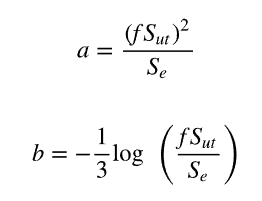

a = (f * S_ultimate)^2 / Se

a = 274.7295

b = (-1/3)*log10(f*S_ultimate/Se)

b = -0.1827

Fatigue strength at 50,000 cycles

N = 50000

N = 50000

S_f_50000 = a * N^b

S_f_50000 = 38.0400

Factor of safety for fatigue

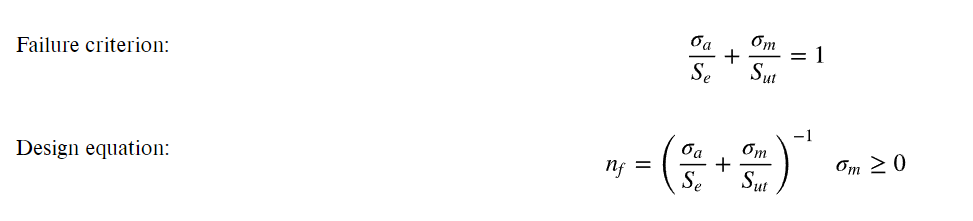

% von mises stresses need to be scaled to kpsi from psi
n_f_50000 = 1/((von_mises_a/1000)/S_f_50000 + (von_mises_m/1000)/S_ultimate)

n_f_50000 = 11.4177

Factor of Safety for yield


$$n_y ={\left(\frac{\sigma_a^{\prime } }{S_y }+\frac{\sigma_m^{\prime } }{S_y }\right)}^{-1} =\left(\frac{S_y }{\sigma_a^{\prime } +\sigma_m^{\prime } }\right)$$


% von mises stresses need to be scaled to kpsi from psi
n_y_50000 = (S_yield/((von_mises_a+von_mises_m)/1000))

n_y_50000 = 19.3123

Create plot of Goodman and Langer Lines with load line present:

figure; hold on

% Goodman Plot
x_goodman = linspace(0,S_ultimate, 2);
y_goodman = (-S_f_50000/S_ultimate)*x_goodman + S_f_50000;
goodman_line = plot(x_goodman, y_goodman, '-o');
goodman_line.MarkerFaceColor = [0, 0, 0];
goodman_line.MarkerSize = 6;


goodman_label = "Goodman Line";
text(0, S_f_50000, 'S_{f}', FontWeight='bold', HorizontalAlignment='right', VerticalAlignment='top');
text(S_ultimate, 0, ' S_{ut}', 'FontWeight','bold')

% Langer Plot
x_langer = linspace(0,S_yield,2);
y_langer = -x_langer + S_yield;
langer_line = plot(x_langer, y_langer, '-o');
langer_line.MarkerFaceColor = [0, 0, 0];
langer_line.MarkerSize = 6;


langer_label = "Langer Line";
text(0, S_yield, 'S_{y} ','FontWeight', 'bold', 'HorizontalAlignment','right');
text(S_yield, 0, 'S_{y}', FontWeight='bold',VerticalAlignment='top', HorizontalAlignment='left')

%Calculate intersection of load and goodman lines
x_intersect_G = S_f_50000*(von_mises_a/von_mises_m + S_f_50000/S_ultimate)^-1

x_intersect_G = 10.9139


%Calculate intersection of load and langer lines
x_intersect_L = S_yield*(von_mises_a/von_mises_m + 1)^-1

x_intersect_L = 18.4602

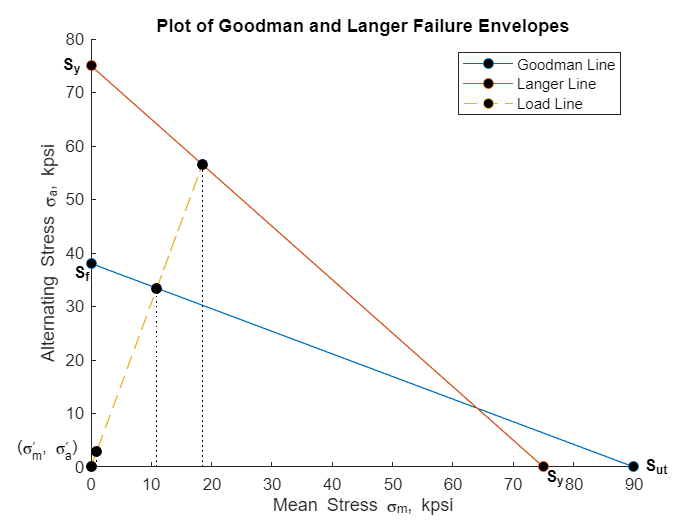


% Load line plot (scale von mises to kpsi from psi)
x_load = [0, von_mises_m/1000, x_intersect_L, x_intersect_G];
y_load = (von_mises_a/von_mises_m)*x_load;
load_line = plot(x_load, y_load,'--o');
load_line.MarkerFaceColor = [0, 0, 0];
load_line.MarkerSize = 6;
load_label = "Load Line";
text(von_mises_m/1000,von_mises_a/1000, '(\sigma_{m}^{\prime}, \sigma_{a}^{\prime})  ', HorizontalAlignment='right')

% Stem for load line
stem(x_load, y_load, ':k')

% Legend for lines
plots = [goodman_line, langer_line, load_line];
labels = [goodman_label, langer_label, load_label];
legend(plots, labels);

% Labels for axes and plot title
xlabel('Mean Stress \sigma_{m}, kpsi')
ylabel('Alternating Stress \sigma_{a}, kpsi');
title('Plot of Goodman and Langer Failure Envelopes')

hold off

Determination of factors of safety from failure envelope plot:

% von Mises stresses must be scales to kpsi from psi
% fatigue
n_f_50000 = x_intersect_G/(von_mises_m/1000)

n_f_50000 = 11.4177

% yield
n_y_50000 = x_intersect_L/(von_mises_m/1000)

n_y_50000 = 19.3123